# From Single-Phase to Three-Phase Systems in MATPOWER

## Using `mp.case_utils.convert_1p_to_3p`

*by: Wilson González Vanegas and Ray Zimmerman*

*July 12, 2025*

From Version 8.0, MATPOWER includes a new prototype Extension API for three-phase models which allows analyzing unbalanced three-phase distribution systems and hybrid transmission (balanced single-phase) / distribution (unbalanced three-phase) systems. It also include several test cases using a data format for prototype elements like three-phase buses, generators, lines, transformers, etc. 

While there are a significant number of single-phase test cases available in MATPOWER, there are not enough three-phase test cases for users to use widely the prototype Extension API for three-phase models.

### Basic concept

The function `mp.case_utils.convert_1p_to_3p()` is intended as a natural mechanism for converting a single-phase MATPOWER case (typically named `mpc`) to its balanced three-phase version (or `mpc3p`). Once this equivalent is created, the user can make simple manual changes for *unbalancing* the network such that the three-phase API can be used.

### 9-Bus Example

#### Load the original case

Take the IEEE 9-bus MATPOWER test case as an example.

mpc = loadcase('case9')

mpc = struct with fields:
    version: '2'
    baseMVA: 100
        bus: [9×13 double]
        gen: [3×21 double]
     branch: [9×13 double]
    gencost: [3×7 double]


### Balanced Three-Phase Example

#### Create the 3-phase balanced case

Using m`p.case_utils.convert_1p_to_3p()`, an equivalent balanced three-phase case can be created automatically with a simple function call.

mpc3p = mp.case_utils.convert_1p_to_3p(mpc)

mpc3p = struct with fields:
    version: '2'
    baseMVA: 100
        bus: []
        gen: []
     branch: []
    gencost: []
       freq: 60
    basekVA: 100000
      bus3p: [9×9 double]
     line3p: [9×6 double]
     xfmr3p: []
    shunt3p: []
     load3p: [3×9 double]
      gen3p: [3×12 double]
         lc: [9×19 double]
    buslink: []


#### Run the power flow

Next, run the power flow for the single-phase case ...

res1p = run_pf(mpc);


MATPOWER Version 8.1, 10-Jul-2025
Power Flow -- AC-polar-power formulation

Newton's method converged in 4 iterations.
PF successful

PF succeeded in 0.18 seconds (0.16 setup + 0.02 solve)
|     System Summary                                                           |
  elements                on     off    total
 --------------------- ------- ------- -------
  Buses                     9       -       9
    Areas                                   1
    Zones                                   1
  Generators                3       -       3
  Loads                     3       -       3
  Branches                  9       -       9
    Lines                   9       -       9
    Transformers            0       -       0

  Total generation                     319.6 MW         22.8 MVAr
  Total max generation capacity        

... and the balanced three-phase equivalent case, checking for balanced results.

res3p_bal = run_pf(mpc3p, mpoption, 'mpx', mp.xt_3p);


MATPOWER Version 8.1, 10-Jul-2025
Power Flow -- AC-polar-power formulation

Newton's method converged in 4 iterations.
PF successful

PF succeeded in 0.54 seconds (0.53 setup + 0.01 solve)
|     System Summary                                                           |
  elements                on     off    total
 --------------------- ------- ------- -------
  3-ph Buses                9       -       9
  3-ph Generators           3       -       3
  3-ph Loads                3       -       3
  3-ph Lines                9       -       9

  Total 3-ph generation             319641.0 kW      22839.9 kVAr
  Total 3-ph load                   315000.0 kW     115000.0 kVAr
  Total 3-ph line loss                4641.0 kW     -92160.1 kVAr

|     3-p

#### Visualize balanced results

We can visualize some comparisons between the two results by looking at the voltage solutions at bus 5 ...

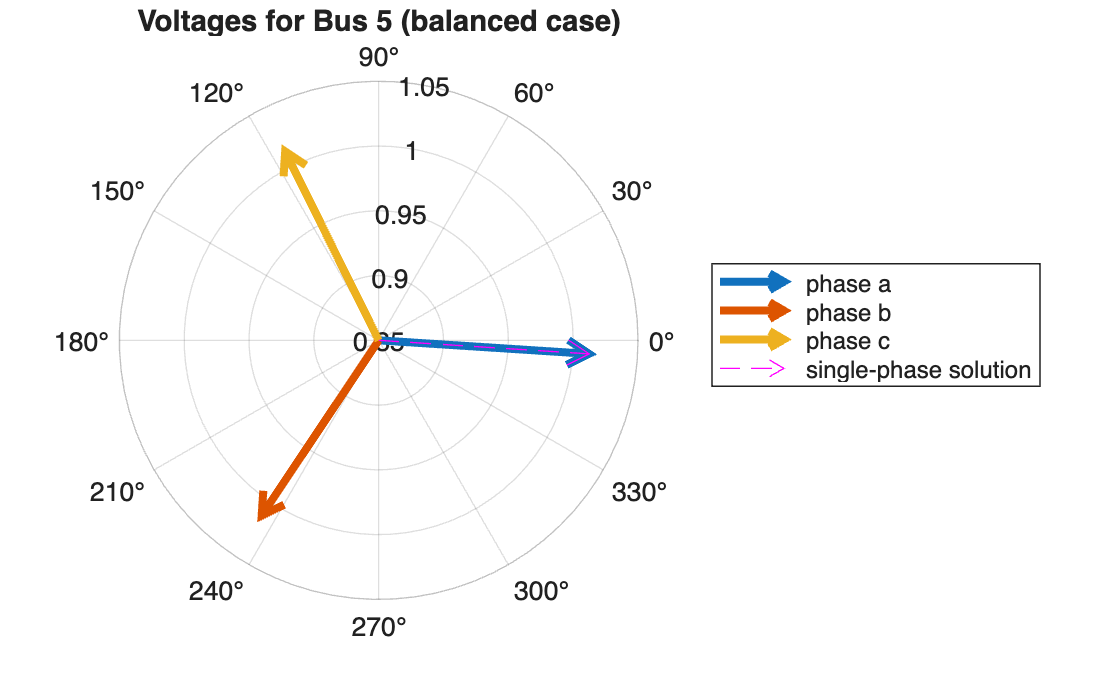

bus_idx = 5;                                    % display voltages at bus 5
bus1p = res1p.dm.elements.bus.tab;              % single-phase bus results
bus3p_bal = res3p_bal.dm.elements.bus3p.tab;    % balanced 3-phase bus results
va1p = bus1p.va(bus_idx);                       % voltage angle of 1p bus
vm1p = bus1p.vm(bus_idx);                       % voltage magnitude of 1p bus
va3pa = bus3p_bal.va1(bus_idx);                 % voltage angle of 3p bus phase a
va3pb = bus3p_bal.va2(bus_idx);                 % voltage angle of 3p bus phase b
va3pc = bus3p_bal.va3(bus_idx);                 % voltage angle of 3p bus phase c
vm3pa = bus3p_bal.vm1(bus_idx);                 % voltage magnitude of 3p bus phase a
vm3pb = bus3p_bal.vm2(bus_idx);                 % voltage magnitude of 3p bus phase b
vm3pc = bus3p_bal.vm3(bus_idx);                 % voltage magnitude of 3p bus phase c

figure;
if exist('compassplot','file')   % use compassplot funtion if available
    compassplot(deg2rad(va3pa), vm3pa, 'LineWidth', 3);
    hold on;
    compassplot(deg2rad(va3pb), vm3pb, 'LineWidth', 3);
    compassplot(deg2rad(va3pc), vm3pc, 'LineWidth', 3);
    compassplot(deg2rad(va1p), vm1p, 'LineStyle', '--', 'Color', 'm');
    hold off;
    set(gca,'Rlim',[0.85 1.05]);
else    % if not, use compass
    [x3p_bal, y3p_bal] = pol2cart(deg2rad([va3pa; va3pb; va3pc]), [vm3pa; vm3pb; vm3pc]);
    [x1p, y1p] = pol2cart(deg2rad(va1p), vm1p);
    pp1 = compass([x3p_bal; x1p], [y3p_bal; y1p]);
    pp1(1).Color = [0 0.4470 0.7410];
    pp1(1).LineWidth = 3;
    pp1(2).Color = [0.8500 0.3250 0.0980];
    pp1(2).LineWidth = 3;
    pp1(3).Color = [0.9290 0.6940 0.1250];
    pp1(3).LineWidth = 3;
    pp1(4).Color = 'm';
    pp1(4).LineWidth = 1;
end
legend({'phase a', 'phase b', 'phase c', 'single-phase solution'},'Location','eastoutside');
title(sprintf('Voltages for Bus %d (balanced case)', bus_idx));

... and the power output of generator 3.

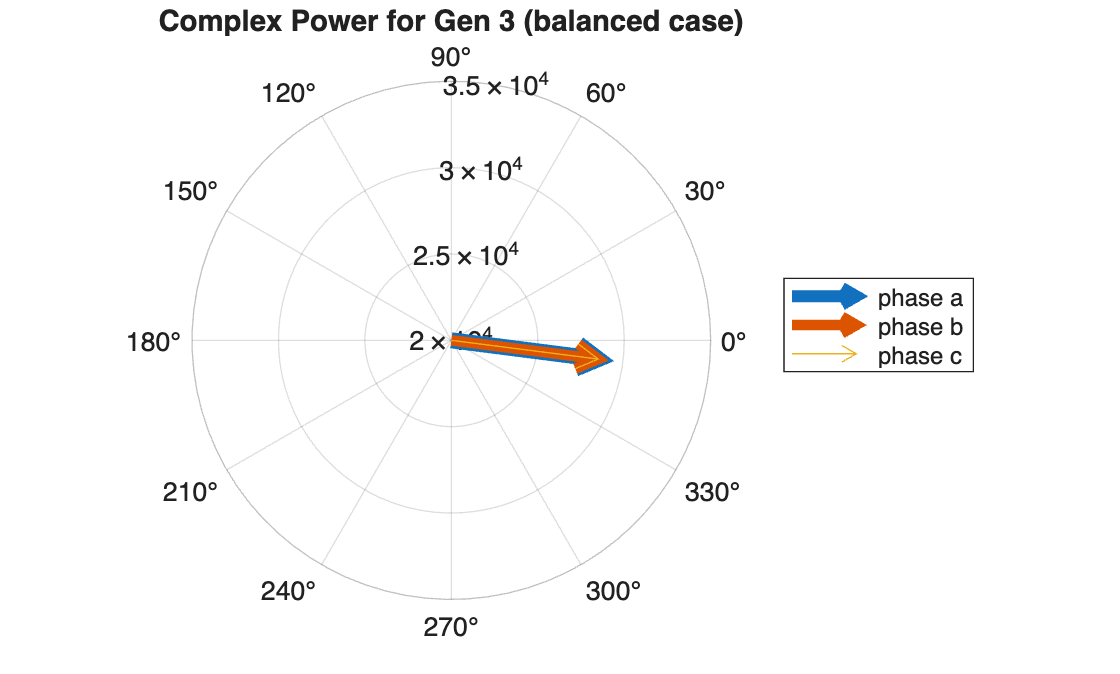

gen_idx = 3;                                    % display generation at gen 3
gen3p_bal = res3p_bal.dm.elements.gen3p.tab;    % unbalanced 3-phase gen results
pg3pa = gen3p_bal.pg1(gen_idx);                 % active power of 3p gen phase a
pg3pb = gen3p_bal.pg2(gen_idx);                 % active power of 3p gen phase b
pg3pc = gen3p_bal.pg3(gen_idx);                 % active power of 3p gen phase c
qg3pa = gen3p_bal.qg1(gen_idx);                 % reactive power of 3p gen phase a
qg3pb = gen3p_bal.qg2(gen_idx);                 % reactive power of 3p gen phase b
qg3pc = gen3p_bal.qg3(gen_idx);                 % reactive power of 3p gen phase c

sg3p = [pg3pa; pg3pb; pg3pc] + 1j * [qg3pa; qg3pb; qg3pc];

figure;
if exist('compassplot','file')   % use compassplot funtion if available
    compassplot(angle(sg3p(1,:)), abs(sg3p(1,:)), 'LineWidth', 6);
    hold on;
    compassplot(angle(sg3p(2,:)), abs(sg3p(2,:)), 'LineWidth', 4);
    compassplot(angle(sg3p(3,:)), abs(sg3p(3,:)), 'LineWidth', 0.5);
    hold off;
    set(gca,'Rlim',[2 3.5]*1e4)
else    % if not, use compass
    pp1 = compass(real(sg3p), imag(sg3p));
    pp1(1).Color = [0 0.4470 0.7410];
    pp1(1).LineWidth = 6;
    pp1(2).Color = [0.8500 0.3250 0.0980];
    pp1(2).LineWidth = 4;
    pp1(3).Color = [0.9290 0.6940 0.1250];
    pp1(3).LineWidth = 0.5;
end
legend({'phase a', 'phase b', 'phase c'},'Location','eastoutside');
title(sprintf('Complex Power for Gen %d (balanced case)', gen_idx));

### Unbalanced Three-Phase Example

Finally, let's unbalance the network via the demand power factors and re-run the power flow.

ldpf = [0.65 0.7 0.97; 0.96 0.75 0.6; 0.95 0.95 0.6];
mpc3p.load3p(:,7:9) = ldpf;     % unbalanced power factors
res3p_unbal = run_pf(mpc3p, mpoption, 'mpx', mp.xt_3p);


MATPOWER Version 8.1, 10-Jul-2025
Power Flow -- AC-polar-power formulation

Newton's method converged in 4 iterations.
PF successful

PF succeeded in 0.27 seconds (0.25 setup + 0.01 solve)
|     System Summary                                                           |
  elements                on     off    total
 --------------------- ------- ------- -------
  3-ph Buses                9       -       9
  3-ph Generators           3       -       3
  3-ph Loads                3       -       3
  3-ph Lines                9       -       9

  Total 3-ph generation             321785.2 kW     181513.6 kVAr
  Total 3-ph load                   315000.0 kW     239708.5 kVAr
  Total 3-ph line loss                6785.2 kW     -58194.9 kVAr

|     3-p

#### Visualize unbalanced results

Now, compare the unbalanced voltage solution at bus 5 ...

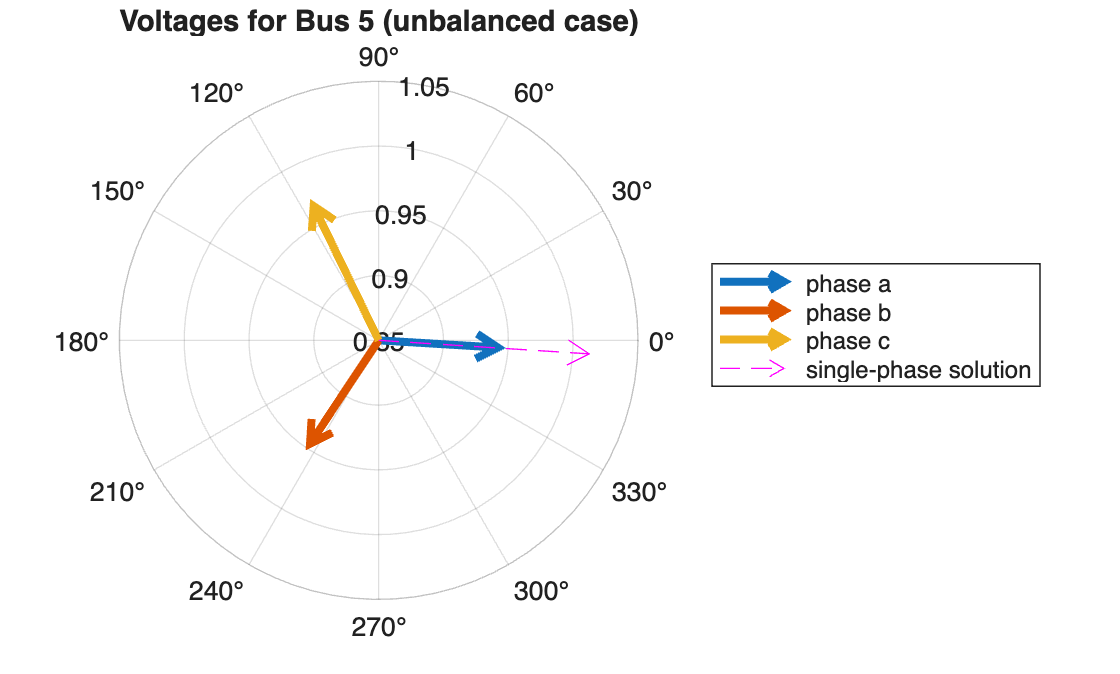

bus_idx = 5;                                        % display voltages at bus 5
bus3p_unbal = res3p_unbal.dm.elements.bus3p.tab;    % unbalanced 3-phase bus results
va3pa = bus3p_unbal.va1(bus_idx);                   % voltage angle of 3p bus phase a
va3pb = bus3p_unbal.va2(bus_idx);                   % voltage angle of 3p bus phase b
va3pc = bus3p_unbal.va3(bus_idx);                   % voltage angle of 3p bus phase c
vm3pa = bus3p_unbal.vm1(bus_idx);                   % voltage magnitude of 3p bus phase a
vm3pb = bus3p_unbal.vm2(bus_idx);                   % voltage magnitude of 3p bus phase b
vm3pc = bus3p_unbal.vm3(bus_idx);                   % voltage magnitude of 3p bus phase c

figure;
if exist('compassplot','file')   % use compassplot funtion if available
    compassplot(deg2rad(va3pa), vm3pa, 'LineWidth', 3);
    hold on;
    compassplot(deg2rad(va3pb), vm3pb, 'LineWidth', 3);
    compassplot(deg2rad(va3pc), vm3pc, 'LineWidth', 3);
    compassplot(deg2rad(va1p), vm1p, 'LineStyle', '--', 'Color', 'm');
    hold off;
    set(gca,'Rlim',[0.85 1.05])
else    % if not, use compass
    [x3p_bal, y3p_bal] = pol2cart(deg2rad([va3pa; va3pb; va3pc]), [vm3pa; vm3pb; vm3pc]);
    [x1p, y1p] = pol2cart(deg2rad(va1p), vm1p);
    pp1 = compass([x3p_bal; x1p], [y3p_bal; y1p]);
    pp1(1).Color = [0 0.4470 0.7410];
    pp1(1).LineWidth = 3;
    pp1(2).Color = [0.8500 0.3250 0.0980];
    pp1(2).LineWidth = 3;
    pp1(3).Color = [0.9290 0.6940 0.1250];
    pp1(3).LineWidth = 3;
    pp1(4).Color = 'm';
    pp1(4).LineWidth = 1;
end
legend({'phase a', 'phase b', 'phase c', 'single-phase solution'},'Location','eastoutside');
title(sprintf('Voltages for Bus %d (unbalanced case)', bus_idx));

... and the unbalanced power output at generator 3.

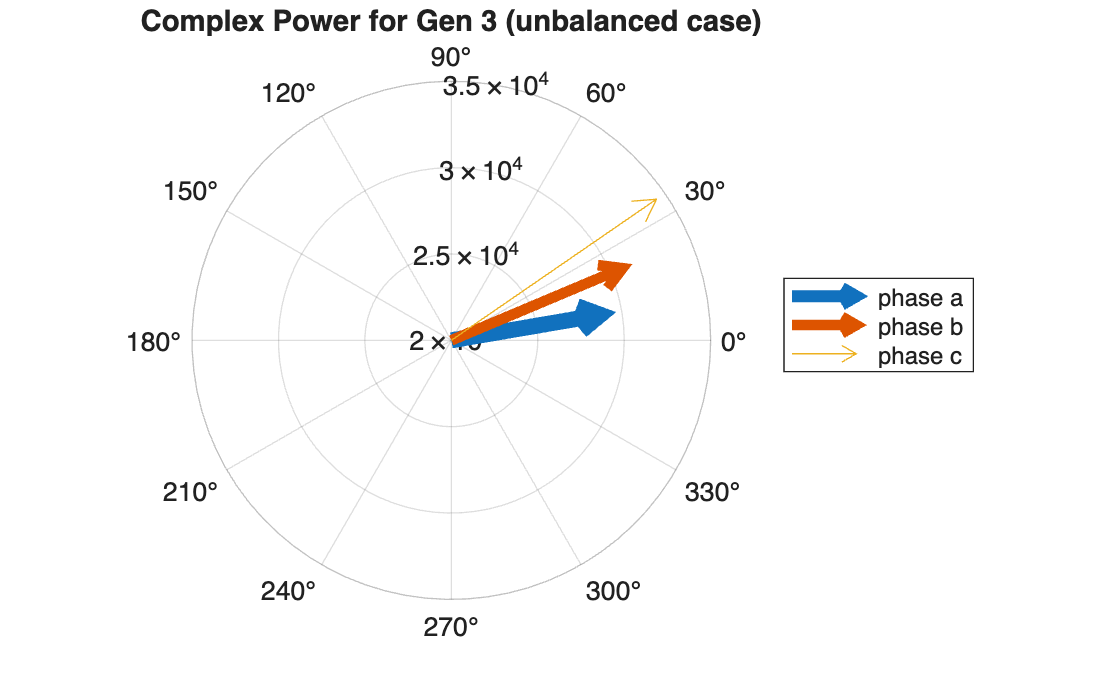

gen_idx = 3;                                      % display generation at gen 3
gen3p_unbal = res3p_unbal.dm.elements.gen3p.tab;  % unbalanced 3-phase gen results
pg3pa = gen3p_unbal.pg1(gen_idx);                 % active power of 3p gen phase a
pg3pb = gen3p_unbal.pg2(gen_idx);                 % active power of 3p gen phase b
pg3pc = gen3p_unbal.pg3(gen_idx);                 % active power of 3p gen phase c
qg3pa = gen3p_unbal.qg1(gen_idx);                 % reactive power of 3p gen phase a
qg3pb = gen3p_unbal.qg2(gen_idx);                 % reactive power of 3p gen phase b
qg3pc = gen3p_unbal.qg3(gen_idx);                 % reactive power of 3p gen phase c

sg3p = [pg3pa; pg3pb; pg3pc] + 1j * [qg3pa; qg3pb; qg3pc]; 

figure;
if exist('compassplot','file')   % use compassplot funtion if available
    compassplot(angle(sg3p(1,:)), abs(sg3p(1,:)), 'LineWidth', 6);
    hold on;
    compassplot(angle(sg3p(2,:)), abs(sg3p(2,:)), 'LineWidth', 4);
    compassplot(angle(sg3p(3,:)), abs(sg3p(3,:)), 'LineWidth', 0.5);
    hold off;
    set(gca,'Rlim',[2 3.5]*1e4)
else    % if not, use compass
    pp1 = compass(real(sg3p), imag(sg3p));
    pp1(1).Color = [0 0.4470 0.7410];
    pp1(1).LineWidth = 6;
    pp1(2).Color = [0.8500 0.3250 0.0980];
    pp1(2).LineWidth = 4;
    pp1(3).Color = [0.9290 0.6940 0.1250];
    pp1(3).LineWidth = 0.5;
end
legend({'phase a', 'phase b', 'phase c'},'Location','eastoutside');
title(sprintf('Complex Power for Gen %d (unbalanced case)', gen_idx));